# Paper3 Function Preparation

## Setting up network

CurrentFolder = pwd

CurrentFolder = '/Users/zhuochengxiao/Library/CloudStorage/OneDrive-Personal/Documents/GitHub/NYU-Vision-2Drive'

%FigurePath = [CurrentFolder '/Figures/Demo022722/'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper3PlotingData/']; % V1D2
addpath(SaveFolder)
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/25Function_Binocular/']; % V1D2
addpath(DataFolder)
DataFolder1 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/16Function_Scheme/LARGE16/']; % V1D2
addpath(DataFolder1)
DataFolder2 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/25Function_binocular_realLGN/']; % V1D2
addpath(DataFolder2)
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

CurrentFolder = pwd; % Since loaded data will overwrite pwd...
FigureFolder = [CurrentFolder '/Paper2Figs/']; % V1D2
%SaveFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/']; % V1
addpath(SaveFolder)

### B1. Load LDE computations and do Fr distributions

Should rerun Sect 1 after in case loaded file contain any paths.

DataPt = 'V4D2';
    load(sprintf("AllMFPixPara_Paper2TuneFig1%s.mat",DataPt))
%load("AllMFPixPara_Paper2TuneFig1V4D2.mat")
%load("AllMFPixPara_Paper2TuneFig1V5D1.mat")
%load("AllMFPixPara_Paper2Tune.mat")
close all
CurrentFolder = pwd;
SaveFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper3PlotingData/']; % V1D2

## 2. Set up LDE firing rate functions

first get basic function information

AngleList = {'0.0','7.5','15.0','22.5'};
LargeFlag = {'S','L','Ler'};
DomList =  {'Small','Large','LARGER'};
lgnSF = 2.5; lgnTF = 10;
for AngCtgr = 1:4% for now; last round: 22.5 broken
    for DomCtgr = 1:length(LargeFlag)
        DomFlag = LargeFlag{DomCtgr};
        DomPrint = DomList{DomCtgr};
        AngPrint = AngleList{AngCtgr};
        Angle = str2num(AngPrint); % can select from 0 7.5 15 22.5
        L6up = 60; L6low = 6;
        ExpTex = 'Final';
        
        LGNStr = sprintf('LGNc%d_SF%.1f_TF%d',1,lgnSF, lgnTF);
        L6Str  = sprintf('L6c%d_uplow%d-%d_%s',1, L6up,L6low, ExpTex);
        FileStr = sprintf(...
                        'Paper3_LIFLib_SIlgn1.1%s_Ang%.1f_%s_%s_%s.mat',...
                                             DataPt, Angle, LGNStr,L6Str,DomFlag);
        load(FileStr,'L4ERcrd','L4IRcrd','f_EnIOut')
        a1 = length(unique(L4ERcrd)); a2 = floor(length(L4ERcrd)/a1);
        rowsmWin = 6; % was 30
        colswWin = 3;
        realLGN = true;
        smth = true;
        if realLGN
            LIFN = 5;
        else
            LIFN = 3;
        end

Load and make all 25 functions for this angle

NOTE: The new scheme include BG inputs for L6 and LGN now!

        LGNlist = 5; L6list = 5; 
        LDEFrVecS = zeros(length(L4ERcrd),LGNlist,L6list);
        LDEFrVecC = zeros(length(L4ERcrd),LGNlist,L6list);
        LDEFrVecI = zeros(length(L4ERcrd),LGNlist,L6list);
        ContourInfoAll = cell(3,LGNlist,L6list); % Use this for E-I relation
        
        plotFlag = false;
        for LGNCtgr = 1:LGNlist
            figure(LGNCtgr)
            for L6Ctgr = 1:L6list
                LGNStr = sprintf('LGNc%d_SF%.1f_TF%d',LGNCtgr,lgnSF, lgnTF);
                L6Str  = sprintf('L6c%d_uplow%d-%d_%s',L6Ctgr, L6up,L6low, ExpTex);
                FileStr = sprintf(...
                    'Paper3_LIFLib_SIlgn1.1%s_Ang%.1f_%s_%s_%s.mat',...
                                             DataPt, Angle, LGNStr,L6Str,DomFlag)
                if exist(FileStr) > 0
                load(FileStr)
                else %% 22.5: (1 4) (2 3) switchable
                    disp("Warning! File non exists, quit...")
                    break
                end
                L4EPlot = reshape(L4ERcrd,a2,a1);
                L4IPlot = reshape(L4IRcrd,a2,a1);
                FrLDE = zeros(length(f_EnIOut),LIFN);
                for LDEInd = 1:length(f_EnIOut)
                    if ~(isempty(f_EnIOut{LDEInd}) || size(f_EnIOut{LDEInd},2)<5)
                        FrLDE(LDEInd,:) = (mean(f_EnIOut{LDEInd}(:,floor(end/2):end),2))';
                    else
                        FrLDE(LDEInd,:) = nan;
                    end
                end
                FrLDE(FrLDE<0) = eps;
                % S rates
                subplot(L6list,3,(L6Ctgr-1)*3+1)
                [LDEFrVecS(:,LGNCtgr,L6Ctgr), ContourInfoAll{1,LGNCtgr,L6Ctgr}]= ...
                    LDEPlotRateFunc_RealLGN(L4EPlot,L4IPlot,FrLDE,a1,a2,...
                    LGNCtgr,L6Ctgr,'S',smth,plotFlag,realLGN, [rowsmWin, colswWin] );
                
                % C rates
                subplot(L6list,3,(L6Ctgr-1)*3+2)
                [LDEFrVecC(:,LGNCtgr,L6Ctgr), ContourInfoAll{2,LGNCtgr,L6Ctgr}] = ...
                    LDEPlotRateFunc_RealLGN(L4EPlot,L4IPlot,FrLDE,a1,a2,...
                    LGNCtgr,L6Ctgr,'C',smth,plotFlag,realLGN, [rowsmWin, colswWin] );
                
                % I rates
                subplot(L6list,3,(L6Ctgr-1)*3+3)
                [LDEFrVecI(:,LGNCtgr,L6Ctgr), ContourInfoAll{3,LGNCtgr,L6Ctgr}] = ...
                    LDEPlotRateFunc_RealLGN(L4EPlot,L4IPlot,FrLDE,a1,a2,...
                    LGNCtgr,L6Ctgr,'I',smth,plotFlag,realLGN, [rowsmWin, colswWin] );
            end
        end
        close all

Create a function

        L4EfuncX = linspace(min(L4ERcrd),max(L4ERcrd),400);
        L4IfuncY = linspace(min(L4IPlot,[],'all'),max(L4IPlot,[],'all'),300);
        [L4EmeshX, L4ImeshY] = meshgrid(L4EfuncX,L4IfuncY);
        
        % 2D function now, depending on input of total E and I kick numbers\
        ItplType = 'Linear';
        for LGNCtgr = 1:LGNlist
            for L6Ctgr = 1:L6list
                LDEFrfunc.S{LGNCtgr,L6Ctgr} = ...
                    griddata(L4ERcrd,L4IRcrd,LDEFrVecS(:,LGNCtgr,L6Ctgr),L4EmeshX, L4ImeshY,ItplType);
                LDEFrfunc.C{LGNCtgr,L6Ctgr} = ...
                    griddata(L4ERcrd,L4IRcrd,LDEFrVecC(:,LGNCtgr,L6Ctgr),L4EmeshX, L4ImeshY,ItplType);
                LDEFrfunc.I{LGNCtgr,L6Ctgr} = ...
                    griddata(L4ERcrd,L4IRcrd,LDEFrVecI(:,LGNCtgr,L6Ctgr),L4EmeshX, L4ImeshY,ItplType);
            end
        end
        %% If 22.5...may need to introduce symmetry
%         if Angle == 22.5
%             LDEFrfuncUse.S = FuncSwap(LDEFrfunc.S,[1,2,3,4;4,3,2,1]);
%             LDEFrfuncUse.C = FuncSwap(LDEFrfunc.C,[1,2,3,4;4,3,2,1]);
%             LDEFrfuncUse.I = FuncSwap(LDEFrfunc.I,[1,2,3,4;4,3,2,1]);
%             LDEFrfunc = LDEFrfuncUse;
%         end
        Comment = ['SIlgn1.1-L6LGN' ExpTex];
        save([SaveFolder sprintf('Func25%s-%s-Ang%s-SF%.1fTF%d-%s.mat',DataPt,Comment,AngPrint,lgnSF,lgnTF,DomPrint)],...
            'LDEFrfunc','L4EmeshX','L4ImeshY')
    end
end

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc1_SF2.5_TF10_L6c1_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc1_SF2.5_TF10_L6c2_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc1_SF2.5_TF10_L6c3_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc1_SF2.5_TF10_L6c4_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc1_SF2.5_TF10_L6c5_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc2_SF2.5_TF10_L6c1_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc2_SF2.5_TF10_L6c2_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc2_SF2.5_TF10_L6c3_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc2_SF2.5_TF10_L6c4_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc2_SF2.5_TF10_L6c5_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc3_SF2.5_TF10_L6c1_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc3_SF2.5_TF10_L6c2_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc3_SF2.5_TF10_L6c3_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc3_SF2.5_TF10_L6c4_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc3_SF2.5_TF10_L6c5_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc4_SF2.5_TF10_L6c1_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc4_SF2.5_TF10_L6c2_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc4_SF2.5_TF10_L6c3_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc4_SF2.5_TF10_L6c4_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc4_SF2.5_TF10_L6c5_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc5_SF2.5_TF10_L6c1_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc5_SF2.5_TF10_L6c2_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc5_SF2.5_TF10_L6c3_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc5_SF2.5_TF10_L6c4_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc5_SF2.5_TF10_L6c5_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc1_SF2.5_TF10_L6c1_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc1_SF2.5_TF10_L6c2_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc1_SF2.5_TF10_L6c3_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc1_SF2.5_TF10_L6c4_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc1_SF2.5_TF10_L6c5_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc2_SF2.5_TF10_L6c1_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc2_SF2.5_TF10_L6c2_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc2_SF2.5_TF10_L6c3_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc2_SF2.5_TF10_L6c4_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc2_SF2.5_TF10_L6c5_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc3_SF2.5_TF10_L6c1_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc3_SF2.5_TF10_L6c2_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc3_SF2.5_TF10_L6c3_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc3_SF2.5_TF10_L6c4_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc3_SF2.5_TF10_L6c5_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc4_SF2.5_TF10_L6c1_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc4_SF2.5_TF10_L6c2_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc4_SF2.5_TF10_L6c3_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc4_SF2.5_TF10_L6c4_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc4_SF2.5_TF10_L6c5_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc5_SF2.5_TF10_L6c1_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc5_SF2.5_TF10_L6c2_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc5_SF2.5_TF10_L6c3_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc5_SF2.5_TF10_L6c4_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc5_SF2.5_TF10_L6c5_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc1_SF2.5_TF10_L6c1_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc1_SF2.5_TF10_L6c2_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc1_SF2.5_TF10_L6c3_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc1_SF2.5_TF10_L6c4_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc1_SF2.5_TF10_L6c5_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc2_SF2.5_TF10_L6c1_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc2_SF2.5_TF10_L6c2_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc2_SF2.5_TF10_L6c3_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc2_SF2.5_TF10_L6c4_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc2_SF2.5_TF10_L6c5_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc3_SF2.5_TF10_L6c1_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc3_SF2.5_TF10_L6c2_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc3_SF2.5_TF10_L6c3_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc3_SF2.5_TF10_L6c4_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc3_SF2.5_TF10_L6c5_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc4_SF2.5_TF10_L6c1_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc4_SF2.5_TF10_L6c2_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc4_SF2.5_TF10_L6c3_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc4_SF2.5_TF10_L6c4_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc4_SF2.5_TF10_L6c5_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc5_SF2.5_TF10_L6c1_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc5_SF2.5_TF10_L6c2_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc5_SF2.5_TF10_L6c3_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc5_SF2.5_TF10_L6c4_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang0.0_LGNc5_SF2.5_TF10_L6c5_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc1_SF2.5_TF10_L6c1_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc1_SF2.5_TF10_L6c2_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc1_SF2.5_TF10_L6c3_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc1_SF2.5_TF10_L6c4_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc1_SF2.5_TF10_L6c5_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc2_SF2.5_TF10_L6c1_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc2_SF2.5_TF10_L6c2_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc2_SF2.5_TF10_L6c3_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc2_SF2.5_TF10_L6c4_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc2_SF2.5_TF10_L6c5_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc3_SF2.5_TF10_L6c1_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc3_SF2.5_TF10_L6c2_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc3_SF2.5_TF10_L6c3_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc3_SF2.5_TF10_L6c4_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc3_SF2.5_TF10_L6c5_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc4_SF2.5_TF10_L6c1_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc4_SF2.5_TF10_L6c2_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc4_SF2.5_TF10_L6c3_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc4_SF2.5_TF10_L6c4_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc4_SF2.5_TF10_L6c5_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc5_SF2.5_TF10_L6c1_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc5_SF2.5_TF10_L6c2_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc5_SF2.5_TF10_L6c3_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc5_SF2.5_TF10_L6c4_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc5_SF2.5_TF10_L6c5_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc1_SF2.5_TF10_L6c1_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc1_SF2.5_TF10_L6c2_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc1_SF2.5_TF10_L6c3_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc1_SF2.5_TF10_L6c4_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc1_SF2.5_TF10_L6c5_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc2_SF2.5_TF10_L6c1_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc2_SF2.5_TF10_L6c2_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc2_SF2.5_TF10_L6c3_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc2_SF2.5_TF10_L6c4_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc2_SF2.5_TF10_L6c5_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc3_SF2.5_TF10_L6c1_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc3_SF2.5_TF10_L6c2_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc3_SF2.5_TF10_L6c3_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc3_SF2.5_TF10_L6c4_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc3_SF2.5_TF10_L6c5_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc4_SF2.5_TF10_L6c1_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc4_SF2.5_TF10_L6c2_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc4_SF2.5_TF10_L6c3_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc4_SF2.5_TF10_L6c4_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc4_SF2.5_TF10_L6c5_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc5_SF2.5_TF10_L6c1_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc5_SF2.5_TF10_L6c2_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc5_SF2.5_TF10_L6c3_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc5_SF2.5_TF10_L6c4_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc5_SF2.5_TF10_L6c5_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc1_SF2.5_TF10_L6c1_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc1_SF2.5_TF10_L6c2_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc1_SF2.5_TF10_L6c3_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc1_SF2.5_TF10_L6c4_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc1_SF2.5_TF10_L6c5_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc2_SF2.5_TF10_L6c1_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc2_SF2.5_TF10_L6c2_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc2_SF2.5_TF10_L6c3_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc2_SF2.5_TF10_L6c4_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc2_SF2.5_TF10_L6c5_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc3_SF2.5_TF10_L6c1_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc3_SF2.5_TF10_L6c2_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc3_SF2.5_TF10_L6c3_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc3_SF2.5_TF10_L6c4_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc3_SF2.5_TF10_L6c5_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc4_SF2.5_TF10_L6c1_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc4_SF2.5_TF10_L6c2_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc4_SF2.5_TF10_L6c3_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc4_SF2.5_TF10_L6c4_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc4_SF2.5_TF10_L6c5_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc5_SF2.5_TF10_L6c1_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc5_SF2.5_TF10_L6c2_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc5_SF2.5_TF10_L6c3_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc5_SF2.5_TF10_L6c4_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang7.5_LGNc5_SF2.5_TF10_L6c5_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc1_SF2.5_TF10_L6c1_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc1_SF2.5_TF10_L6c2_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc1_SF2.5_TF10_L6c3_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc1_SF2.5_TF10_L6c4_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc1_SF2.5_TF10_L6c5_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc2_SF2.5_TF10_L6c1_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc2_SF2.5_TF10_L6c2_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc2_SF2.5_TF10_L6c3_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc2_SF2.5_TF10_L6c4_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc2_SF2.5_TF10_L6c5_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc3_SF2.5_TF10_L6c1_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc3_SF2.5_TF10_L6c2_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc3_SF2.5_TF10_L6c3_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc3_SF2.5_TF10_L6c4_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc3_SF2.5_TF10_L6c5_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc4_SF2.5_TF10_L6c1_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc4_SF2.5_TF10_L6c2_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc4_SF2.5_TF10_L6c3_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc4_SF2.5_TF10_L6c4_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc4_SF2.5_TF10_L6c5_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc5_SF2.5_TF10_L6c1_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc5_SF2.5_TF10_L6c2_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc5_SF2.5_TF10_L6c3_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc5_SF2.5_TF10_L6c4_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc5_SF2.5_TF10_L6c5_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc1_SF2.5_TF10_L6c1_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc1_SF2.5_TF10_L6c2_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc1_SF2.5_TF10_L6c3_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc1_SF2.5_TF10_L6c4_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc1_SF2.5_TF10_L6c5_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc2_SF2.5_TF10_L6c1_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc2_SF2.5_TF10_L6c2_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc2_SF2.5_TF10_L6c3_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc2_SF2.5_TF10_L6c4_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc2_SF2.5_TF10_L6c5_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc3_SF2.5_TF10_L6c1_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc3_SF2.5_TF10_L6c2_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc3_SF2.5_TF10_L6c3_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc3_SF2.5_TF10_L6c4_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc3_SF2.5_TF10_L6c5_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc4_SF2.5_TF10_L6c1_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc4_SF2.5_TF10_L6c2_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc4_SF2.5_TF10_L6c3_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc4_SF2.5_TF10_L6c4_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc4_SF2.5_TF10_L6c5_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc5_SF2.5_TF10_L6c1_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc5_SF2.5_TF10_L6c2_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc5_SF2.5_TF10_L6c3_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc5_SF2.5_TF10_L6c4_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc5_SF2.5_TF10_L6c5_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc1_SF2.5_TF10_L6c1_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc1_SF2.5_TF10_L6c2_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc1_SF2.5_TF10_L6c3_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc1_SF2.5_TF10_L6c4_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc1_SF2.5_TF10_L6c5_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc2_SF2.5_TF10_L6c1_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc2_SF2.5_TF10_L6c2_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc2_SF2.5_TF10_L6c3_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc2_SF2.5_TF10_L6c4_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc2_SF2.5_TF10_L6c5_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc3_SF2.5_TF10_L6c1_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc3_SF2.5_TF10_L6c2_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc3_SF2.5_TF10_L6c3_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc3_SF2.5_TF10_L6c4_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc3_SF2.5_TF10_L6c5_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc4_SF2.5_TF10_L6c1_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc4_SF2.5_TF10_L6c2_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc4_SF2.5_TF10_L6c3_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc4_SF2.5_TF10_L6c4_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc4_SF2.5_TF10_L6c5_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc5_SF2.5_TF10_L6c1_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc5_SF2.5_TF10_L6c2_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc5_SF2.5_TF10_L6c3_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc5_SF2.5_TF10_L6c4_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang15.0_LGNc5_SF2.5_TF10_L6c5_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc1_SF2.5_TF10_L6c1_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc1_SF2.5_TF10_L6c2_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc1_SF2.5_TF10_L6c3_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc1_SF2.5_TF10_L6c4_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc1_SF2.5_TF10_L6c5_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc2_SF2.5_TF10_L6c1_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc2_SF2.5_TF10_L6c2_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc2_SF2.5_TF10_L6c3_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc2_SF2.5_TF10_L6c4_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc2_SF2.5_TF10_L6c5_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc3_SF2.5_TF10_L6c1_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc3_SF2.5_TF10_L6c2_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc3_SF2.5_TF10_L6c3_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc3_SF2.5_TF10_L6c4_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc3_SF2.5_TF10_L6c5_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc4_SF2.5_TF10_L6c1_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc4_SF2.5_TF10_L6c2_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc4_SF2.5_TF10_L6c3_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc4_SF2.5_TF10_L6c4_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc4_SF2.5_TF10_L6c5_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc5_SF2.5_TF10_L6c1_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc5_SF2.5_TF10_L6c2_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc5_SF2.5_TF10_L6c3_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc5_SF2.5_TF10_L6c4_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc5_SF2.5_TF10_L6c5_uplow60-6_Final_S.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc1_SF2.5_TF10_L6c1_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc1_SF2.5_TF10_L6c2_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc1_SF2.5_TF10_L6c3_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc1_SF2.5_TF10_L6c4_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc1_SF2.5_TF10_L6c5_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc2_SF2.5_TF10_L6c1_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc2_SF2.5_TF10_L6c2_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc2_SF2.5_TF10_L6c3_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc2_SF2.5_TF10_L6c4_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc2_SF2.5_TF10_L6c5_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc3_SF2.5_TF10_L6c1_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc3_SF2.5_TF10_L6c2_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc3_SF2.5_TF10_L6c3_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc3_SF2.5_TF10_L6c4_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc3_SF2.5_TF10_L6c5_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc4_SF2.5_TF10_L6c1_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc4_SF2.5_TF10_L6c2_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc4_SF2.5_TF10_L6c3_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc4_SF2.5_TF10_L6c4_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc4_SF2.5_TF10_L6c5_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc5_SF2.5_TF10_L6c1_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc5_SF2.5_TF10_L6c2_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc5_SF2.5_TF10_L6c3_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc5_SF2.5_TF10_L6c4_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc5_SF2.5_TF10_L6c5_uplow60-6_Final_L.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc1_SF2.5_TF10_L6c1_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc1_SF2.5_TF10_L6c2_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc1_SF2.5_TF10_L6c3_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc1_SF2.5_TF10_L6c4_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc1_SF2.5_TF10_L6c5_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc2_SF2.5_TF10_L6c1_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc2_SF2.5_TF10_L6c2_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc2_SF2.5_TF10_L6c3_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc2_SF2.5_TF10_L6c4_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc2_SF2.5_TF10_L6c5_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc3_SF2.5_TF10_L6c1_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc3_SF2.5_TF10_L6c2_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc3_SF2.5_TF10_L6c3_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc3_SF2.5_TF10_L6c4_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc3_SF2.5_TF10_L6c5_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc4_SF2.5_TF10_L6c1_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc4_SF2.5_TF10_L6c2_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc4_SF2.5_TF10_L6c3_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc4_SF2.5_TF10_L6c4_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc4_SF2.5_TF10_L6c5_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc5_SF2.5_TF10_L6c1_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc5_SF2.5_TF10_L6c2_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc5_SF2.5_TF10_L6c3_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc5_SF2.5_TF10_L6c4_uplow60-6_Final_Ler.mat'

FileStr = 'Paper3_LIFLib_SIlgn1.1V4D2_Ang22.5_LGNc5_SF2.5_TF10_L6c5_uplow60-6_Final_Ler.mat'

Compare realLGN and fake local response functions

AngleList = {'0.0','7.5','15.0','22.5'};
LargeFlag = {'S','L','Ler'};
DomList =  {'Small','Large','LARGER'};
ExpTex = 'Final';
Comment = ['SIlgn1.1-L6LGN' ExpTex];
lgnSF = 2.5; lgnTF = 10;
DomCtgr = 1;
DomFlag = LargeFlag{DomCtgr};
DomPrint = DomList{DomCtgr};
AngPrint = AngleList{1};
LRF_real = load([sprintf('Func25%s-%s-Ang%s-SF%.1fTF%d-%s.mat',DataPt,Comment,AngPrint,lgnSF,lgnTF,DomPrint)],...
           'LDEFrfunc','L4EmeshX','L4ImeshY');
LRF_fake = load([sprintf('Func25%sAng%s-SF%.1fTF%d-%s.mat',DataPt,AngPrint,lgnSF,lgnTF,DomPrint)],...
            'LDEFrfunc','L4EmeshX','L4ImeshY');

% LRF_fake = load([sprintf('Func25%sAng%s%s.mat',DataPt,AngPrint,DomPrint)],...
%             'LDEFrfunc','L4EmeshX','L4ImeshY');
L4EmeshX = LRF_real.L4EmeshX;
L4ImeshY = LRF_real.L4ImeshY;

make figure

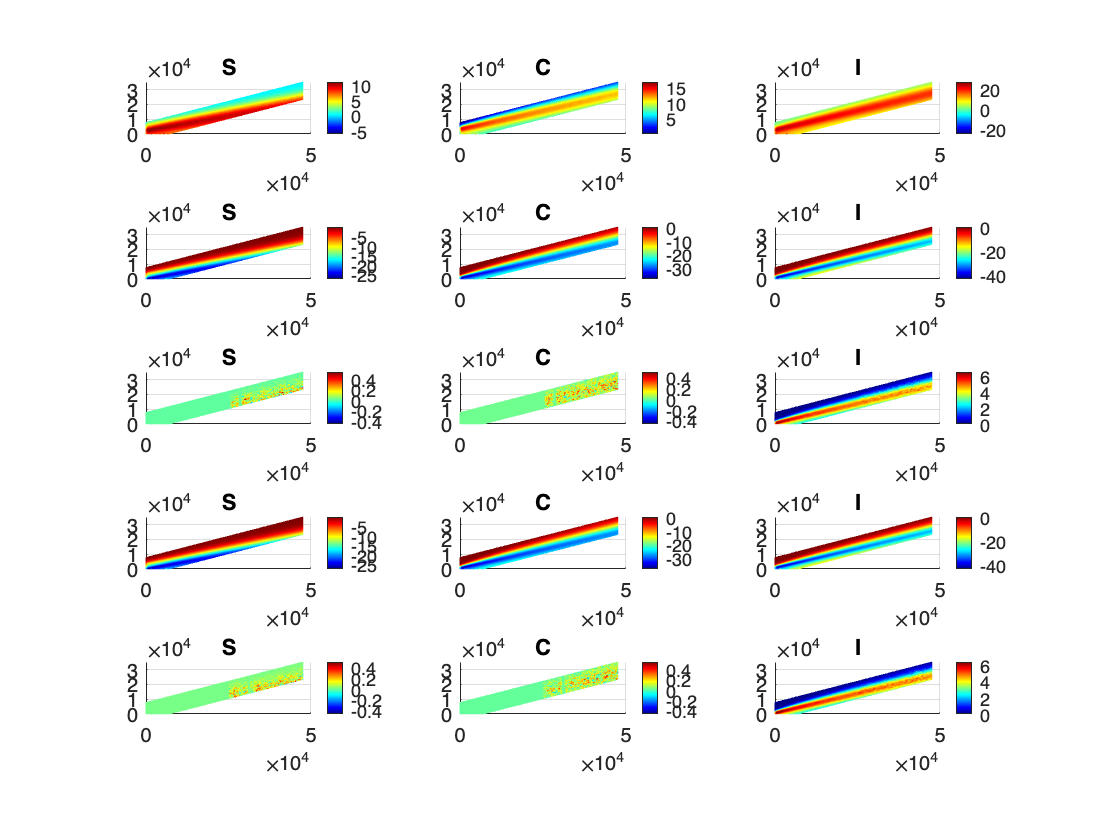

close all
figure(2)
L6list = 5; 
for L6Ctgr = 1:L6list
    % S rate diff
    subplot(L6list,3,(L6Ctgr-1)*3+1)
    mesh(L4EmeshX,L4ImeshY,...
        LRF_real.LDEFrfunc.S{1,L6Ctgr} - LRF_fake.LDEFrfunc.S{1,L6Ctgr} )
    colormap jet
    colorbar
    %caxis([-5 5])
    view([0 90])
    title('S')
    % C rate diff
    subplot(L6list,3,(L6Ctgr-1)*3+2)
    mesh(L4EmeshX,L4ImeshY,...
        LRF_real.LDEFrfunc.C{1,L6Ctgr} - LRF_fake.LDEFrfunc.C{1,L6Ctgr} )
    colormap jet
    colorbar
    %caxis([-5 5])
    view([0 90])
    title('C')
    % C rate diff
    subplot(L6list,3,(L6Ctgr-1)*3+3)
    mesh(L4EmeshX,L4ImeshY,...
        LRF_real.LDEFrfunc.I{1,L6Ctgr} - LRF_fake.LDEFrfunc.I{1,L6Ctgr} )
    colormap jet
    colorbar
    %caxis([-5 5])
    view([0 90])
    title('I')
end

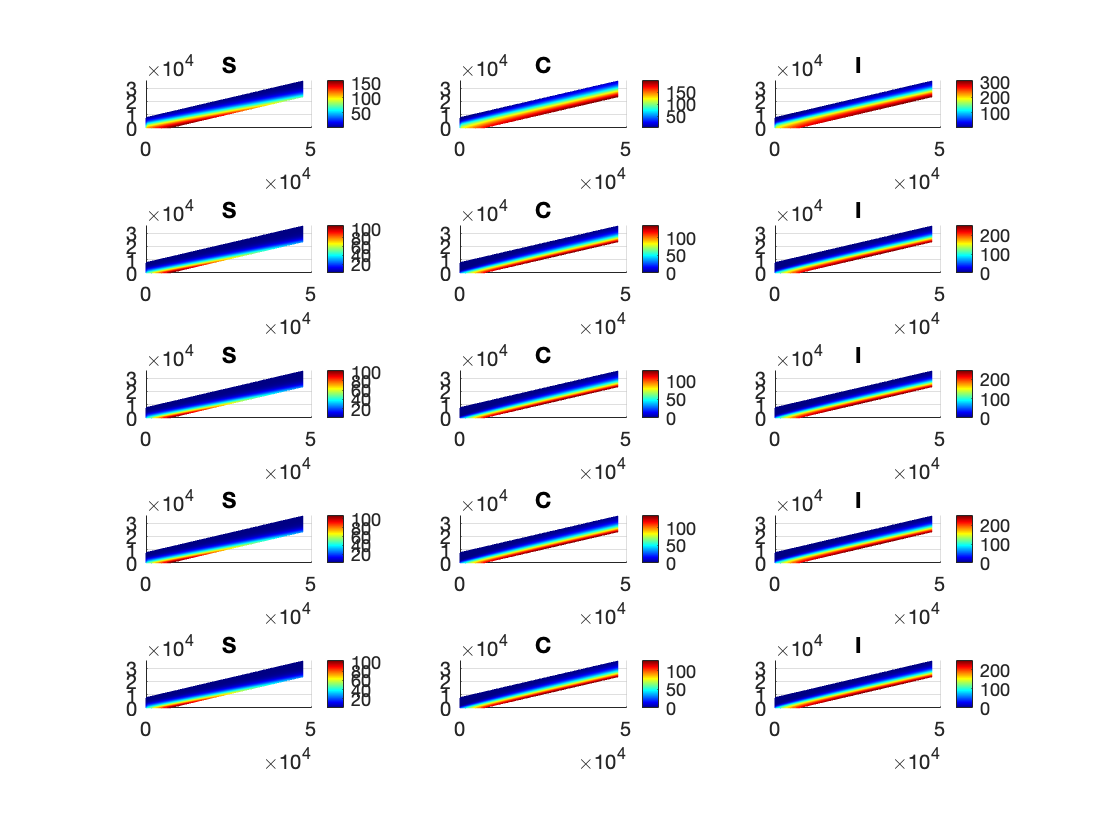

figure(3)
for L6Ctgr = 1:L6list
    % S rate diff
    subplot(L6list,3,(L6Ctgr-1)*3+1)
    mesh(L4EmeshX,L4ImeshY,...
        LRF_real.LDEFrfunc.S{1,L6Ctgr})
    colormap jet
    colorbar
    %caxis([-5 5])
    view([0 90])
    title('S')
    % C rate diff
    subplot(L6list,3,(L6Ctgr-1)*3+2)
    mesh(L4EmeshX,L4ImeshY,...
        LRF_real.LDEFrfunc.C{1,L6Ctgr} )
    colormap jet
    colorbar
    %caxis([-5 5])
    view([0 90])
    title('C')
    % C rate diff
    subplot(L6list,3,(L6Ctgr-1)*3+3)
    mesh(L4EmeshX,L4ImeshY,...
        LRF_real.LDEFrfunc.I{1,L6Ctgr} )
    colormap jet
    colorbar
    %caxis([-5 5])
    view([0 90])
    title('I')
end